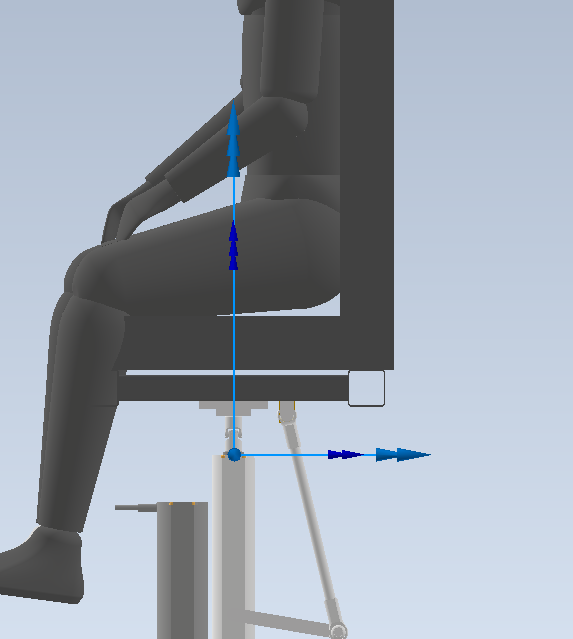

clear

A1=readtable("MatLab cinetica\Reacciones actuador central\A1.txt","Delimiter"," ");

A1.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];

A2=readtable("MatLab cinetica\Reacciones actuador central\A2.txt","Delimiter"," ");

A2.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];

A3=readtable("MatLab cinetica\Reacciones actuador central\A3.txt","Delimiter"," ");

A3.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];

B1=readtable("MatLab cinetica\Reacciones actuador central\B1.txt","Delimiter"," ");

B1.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];

B2=readtable("MatLab cinetica\Reacciones actuador central\B2.txt","Delimiter"," ");

B2.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];

B3=readtable("MatLab cinetica\Reacciones actuador central\B3.txt","Delimiter"," ");

B3.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];

C1=readtable("MatLab cinetica\Reacciones actuador central\C1.txt","Delimiter"," ");

C1.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];

C2=readtable("MatLab cinetica\Reacciones actuador central\C2.txt","Delimiter"," ");

C2.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];

C3=readtable("MatLab cinetica\Reacciones actuador central\C3.txt","Delimiter"," ");

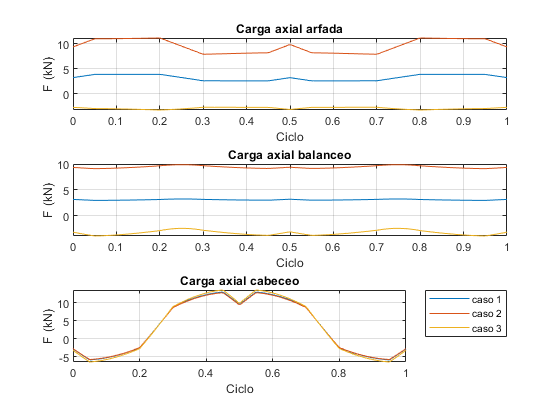

C3.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];

CargaAxialA1=A1.Fz;
CargaAxialA2=A2.Fz;
CargaAxialA3=A3.Fz;

CargaAxialB1=B1.Fz;
CargaAxialB2=B2.Fz;
CargaAxialB3=B3.Fz;

CargaAxialC1=C1.Fz;
CargaAxialC2=C2.Fz;
CargaAxialC3=C3.Fz;



figure()
subplot(3,1,1)
plot(linspace(0,1,160),CargaAxialA1/1000)
hold on
plot(linspace(0,1,160),CargaAxialA2/1000)
plot(linspace(0,1,160),CargaAxialA3/1000)
hold off
%legend("caso 1","caso 2","caso 3","Location","best")
title("Carga axial arfada")
xlabel('Ciclo')
ylabel('F (kN)')
grid on

subplot(3,1,2)
plot(linspace(0,1,160),CargaAxialB1/1000)
hold on
plot(linspace(0,1,160),CargaAxialB2/1000)
plot(linspace(0,1,160),CargaAxialB3/1000)
hold off
%legend("caso 1","caso 2","caso 3","Location","best")
title("Carga axial balanceo")
xlabel('Ciclo')
ylabel('F (kN)')
grid on


subplot(3,1,3)
plot(linspace(0,1,160),CargaAxialC1/1000)
hold on
plot(linspace(0,1,160),CargaAxialC2/1000)
plot(linspace(0,1,160),CargaAxialC3/1000)
hold off
legend("caso 1","caso 2","caso 3","Location","bestoutside")
title("Carga axial cabeceo")
xlabel('Ciclo')
ylabel('F (kN)')
grid on




maxVCCargaAxial=max([CargaAxialA1;CargaAxialA2;CargaAxialA3;CargaAxialB1;CargaAxialB2;CargaAxialB3;CargaAxialC1;CargaAxialC2;CargaAxialC3]);
disp("Carga axial máxima: "+maxVCCargaAxial+" N")

Carga axial máxima: 13528.2 N


FmA1=Fm(abs(CargaAxialA1))

FmA1 = 3.2941e+03

FmA2=Fm(abs(CargaAxialA2))

FmA2 = 9.7313e+03

FmA3=Fm(abs(CargaAxialA3))

FmA3 = 2.9858e+03


FmB1=Fm(abs(CargaAxialB1))

FmB1 = 3.0710e+03

FmB2=Fm(abs(CargaAxialB2))

FmB2 = 9.4112e+03

FmB3=Fm(abs(CargaAxialB3))

FmB3 = 3.3764e+03


FmC1=Fm(abs(CargaAxialC1))

FmC1 = 8.7188e+03

FmC2=Fm(abs(CargaAxialC2))

FmC2 = 8.6114e+03

FmC3=Fm(abs(CargaAxialC3))

FmC3 = 9.0728e+03



CargaAxialA1=A1.Fz;
CargaAxialA2=A2.Fz;
CargaAxialA3=A3.Fz;

CargaAxialB1=B1.Fz;
CargaAxialB2=B2.Fz;
CargaAxialB3=B3.Fz;

CargaAxialC1=C1.Fz;
CargaAxialC2=C2.Fz;
CargaAxialC3=C3.Fz;





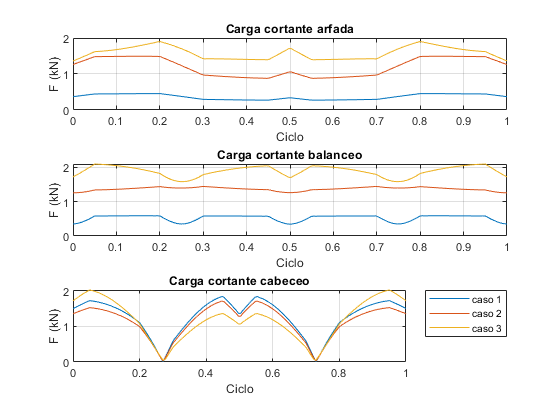


CargaCortanteA1=sqrt(A1.Fx.^2+A1.Fy.^2);
CargaCortanteA2=sqrt(A2.Fx.^2+A2.Fy.^2);
CargaCortanteA3=sqrt(A3.Fx.^2+A3.Fy.^2);
CargaCortanteB1=sqrt(B1.Fx.^2+B1.Fy.^2);
CargaCortanteB2=sqrt(B2.Fx.^2+B2.Fy.^2);
CargaCortanteB3=sqrt(B3.Fx.^2+B3.Fy.^2);
CargaCortanteC1=sqrt(C1.Fx.^2+C1.Fy.^2);
CargaCortanteC2=sqrt(C2.Fx.^2+C2.Fy.^2);
CargaCortanteC3=sqrt(C3.Fx.^2+C3.Fy.^2);



figure()
subplot(3,1,1)
plot(linspace(0,1,160),CargaCortanteA1/1000)
hold on
plot(linspace(0,1,160),CargaCortanteA2/1000)
plot(linspace(0,1,160),CargaCortanteA3/1000)
hold off
%legend("caso 1","caso 2","caso 3","Location","best")
title("Carga cortante arfada")
xlabel('Ciclo')
ylabel('F (kN)')
grid on

subplot(3,1,2)
plot(linspace(0,1,160),CargaCortanteB1/1000)
hold on
plot(linspace(0,1,160),CargaCortanteB2/1000)
plot(linspace(0,1,160),CargaCortanteB3/1000)
hold off
%legend("caso 1","caso 2","caso 3","Location","best")
title("Carga cortante balanceo")
xlabel('Ciclo')
ylabel('F (kN)')
grid on


subplot(3,1,3)
plot(linspace(0,1,160),CargaCortanteC1/1000)
hold on
plot(linspace(0,1,160),CargaCortanteC2/1000)
plot(linspace(0,1,160),CargaCortanteC3/1000)
hold off
legend("caso 1","caso 2","caso 3","Location","bestoutside")
title("Carga cortante cabeceo")
xlabel('Ciclo')
ylabel('F (kN)')
grid on



maxCargaCortante=max([CargaCortanteA1;CargaCortanteA2;CargaCortanteA3;CargaCortanteB1;CargaCortanteB2;CargaCortanteB3;CargaCortanteC1;CargaCortanteC2;CargaCortanteC3]);
disp("Carga cortante máxima: "+maxCargaCortante+" N")

Carga cortante máxima: 2099.0555 N


ans = 807.6270

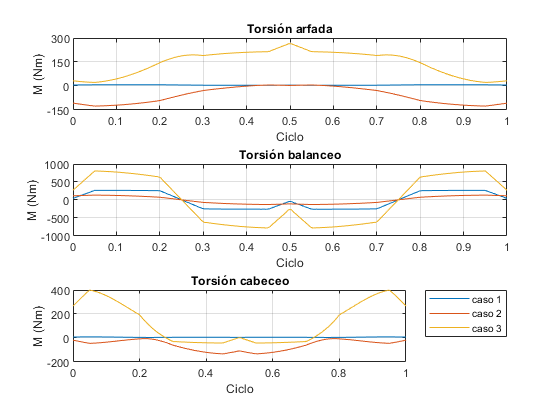

figure()
subplot(3,1,1)
plot(linspace(0,1,160),A1.Mz/1000)
hold on
plot(linspace(0,1,160),A2.Mz/1000)
plot(linspace(0,1,160),A3.Mz/1000)
hold off
%legend("caso 1","caso 2","caso 3","Location","best")
title("Torsión arfada")
xlabel('Ciclo')
ylabel('M (Nm)')
yticks(-150:150:300)
ylim([-150 300])
grid on

subplot(3,1,2)
plot(linspace(0,1,160),B1.Mz/1000)
hold on
plot(linspace(0,1,160),B2.Mz/1000)
plot(linspace(0,1,160),B3.Mz/1000)
hold off
%legend("caso 1","caso 2","caso 3","Location","best")
title("Torsión balanceo")
xlabel('Ciclo')
yticks(-1000:500:1000)

ylabel('M (Nm)')
grid on


subplot(3,1,3)
plot(linspace(0,1,160),C1.Mz/1000)
hold on
plot(linspace(0,1,160),C2.Mz/1000)
plot(linspace(0,1,160),C3.Mz/1000)
hold off
legend("caso 1","caso 2","caso 3","Location","bestoutside")
title("Torsión cabeceo")
xlabel('Ciclo')
ylabel('M (Nm)')
yticks(-200:200:400)
ylim([-200 400])
grid on

function F=Fm(CargaAxial)
    L=length(CargaAxial);
    
    F=(sum(CargaAxial.^3)/160)^(1/3);
end
